% example script that recreates the plots shown in the README document
close all;
clear all;

% Change this data file name below to plot different files
load('data/Matlab/RW9')

## First we show a sample plot of the low current discharge data

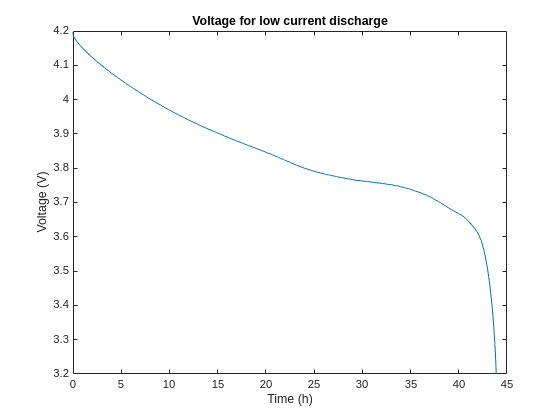

steps = data.step; % save steps array to new variable

% search for instances of low current discharge step
inds = []; % initialize index array
for(i=1:length(steps))
    if(strcmp(data.step(i).comment,'low current discharge at 0.04A'))
        inds = [inds, i];
    end
end

% plot data from first low current discharge step
RT = steps(inds(1)).relativeTime/3600; % relative time in hours
V = steps(inds(1)).voltage; % voltage
I = steps(inds(1)).current; % current

figure % plot voltage profile
plot(RT,V)
title('Voltage for low current discharge')
xlabel('Time (h)');
ylabel('Voltage (V)');

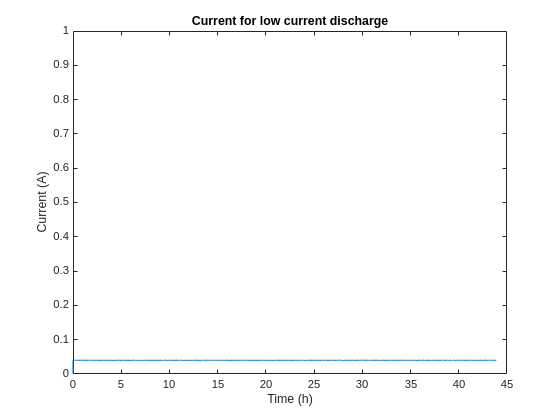


figure % plot current profile
plot(RT,I)
title('Current for low current discharge')
ylim([0,1])
xlabel('Time (h)');
ylabel('Current (A)');

## Next, the constant load profiles that are run after every 50 random walk

discharge cycles are plotted using

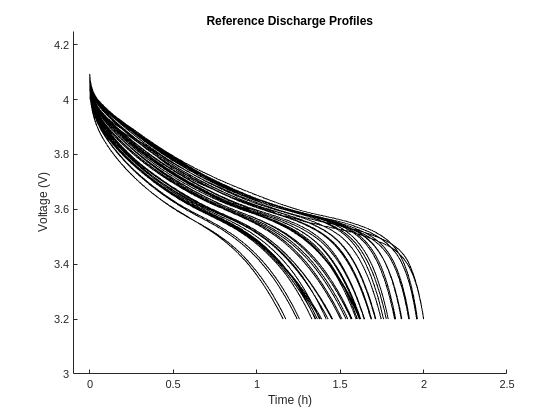

04-Jan-2014 02:28:25
04-Jan-2014 08:06:47
09-Jan-2014 08:41:35
09-Jan-2014 13:58:24
14-Jan-2014 02:18:01
14-Jan-2014 07:40:19
18-Jan-2014 19:31:46
19-Jan-2014 00:53:58
24-Jan-2014 08:50:05
24-Jan-2014 14:07:15
29-Jan-2014 15:06:56
29-Jan-2014 20:29:17
04-Feb-2014 05:24:20
04-Feb-2014 10:47:46
09-Feb-2014 08:20:41
09-Feb-2014 13:49:11
14-Feb-2014 07:39:41
14-Feb-2014 13:10:03
19-Feb-2014 14:07:27
19-Feb-2014 19:43:46
24-Feb-2014 18:52:03
25-Feb-2014 00:33:56
01-Mar-2014 19:06:14
02-Mar-2014 00:49:27
08-Mar-2014 19:13:00
09-Mar-2014 04:18:12
16-Mar-2014 07:17:48
16-Mar-2014 15:19:42
23-Mar-2014 12:55:16
23-Mar-2014 21:03:02
31-Mar-2014 06:58:59
31-Mar-2014 15:12:00
07-Apr-2014 19:51:53
08-Apr-2014 04:18:56
14-Apr-2014 16:25:55
15-Apr-2014 01:02:51
21-Apr-2014 08:15:39
21-Apr-2014 17:02:16
28-Apr-2014 22:13:14
29-Apr-2014 06:49:15
06-May-2014 04:11:31
06-May-2014 12:59:04
13-May-2014 20:57:36
14-May-2014 05:37:50
21-May-2014 03:47:19
21-May-2014 12:25:59
27-May-2014 10:30:28
27-May-2014 1

% initialize plot
figure, hold on
xlim([-.1,2.5])
ylim([3,4.25])
xlabel('Time (h)');
ylabel('Voltage (V)');
title('Reference Discharge Profiles')

for i = 1:length(steps) % search through the array of step structures
    if strcmp(steps(i).comment,'reference discharge')
        RT = steps(i).relativeTime/3600; % relative time in hours
        V = steps(i).voltage; % voltage
        disp(steps(i).date);
        plot(RT,V,'k')
    end
end

## We can benchmark the battery?s capacity by integrating current over the

reference cycles. The next plot shows this capacity measurement vs date.

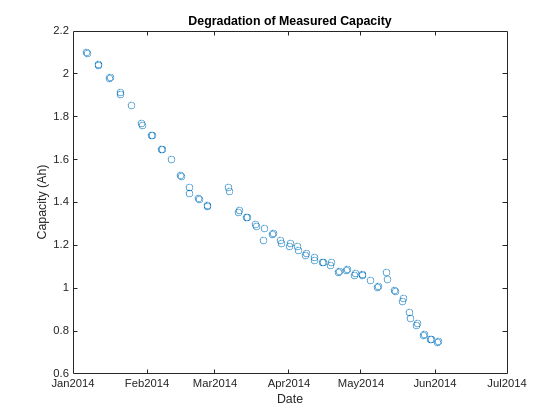

counter = 0; % initialize counters

for i = 1:length(steps) % search through the array of step structures
    if strcmp(steps(i).comment,'reference discharge')
        counter = counter+1;

        % save the date of this reference discharge step
        date(counter) = datenum(steps(i).date);

        % save the battery capacity measured by integrating current
        capacity(counter) = trapz(steps(i).relativeTime/3600,data.step(i).current);
    end
end

% plot the data
figure
plot(date,capacity,'o')
datetick('x','mmmyyyy')
xlabel('Date');
ylabel('Capacity (Ah)');
title('Degradation of Measured Capacity')

## The next code snippet shows how the resting periods after each reference

discharge can be grouped with the corresponding reference discharge cycle and added to the plot above.

% Initialize Reference Charge Struct that will hold indexes of reference
% charge steps and the rest steps that come immediately before and after
RefChg.repition{1}.indexes = 0;

% Initialize loop parameters
counter = 0;
for i = 1:length(data.step)
    if strcmp(steps(i).comment, 'reference charge')
        counter = counter + 1;
        if strcmp(steps(i-1).comment, 'rest post reference discharge')
            RefChg.repition{counter}.indexes = [i-1, i];
        else
            RefChg.repition{counter}.indexes = i;
        end
    end

    if strcmp(steps(i).comment, 'rest post reference charge')
        RefChg.repition{counter}.indexes = [RefChg.repition{counter}.indexes, i];
    end
end

Array indices must be positive integers or logical values.


% Now plot each of the grouped reference charge cycles
figure, hold on
for i = 1:length(RefChg.repition)
    % Stitch together all of the substeps identified in the repetition field
    step = steps(RefChg.repition{i}.indexes(1));

    % If the first index is a rest period, then make it end at relativeTime == 0
    if strcmp(step.comment, 'rest post reference discharge')
        step.relativeTime = step.relativeTime - step.relativeTime(end);
    end

    for j = 2:length(RefChg.repition{i}.indexes)
        step.relativeTime = [step.relativeTime step.relativeTime(end) + steps(RefChg.repition{i}.indexes(j)).relativeTime];
        step.voltage = [step.voltage steps(RefChg.repition{i}.indexes(j)).voltage];
        step.current = [step.current steps(RefChg.repition{i}.indexes(j)).current];
        step.temperature = [step.temperature steps(RefChg.repition{i}.indexes(j)).temperature];
    end

    plot(step.relativeTime/3600, step.voltage, 'k')
    title('Reference charge profiles and post-charge rest periods')
    xlabel('Time (h)')
    ylabel('Voltage (V)')
end


## Example Plots of Pulsed Load Charging and Discharging Cycles

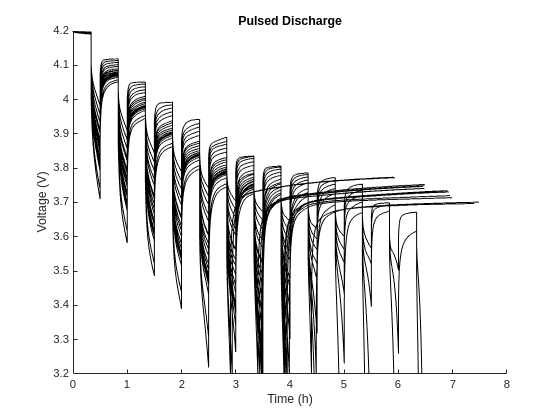

PulsedDis.repition{1}.indexes = 0;
counter1 = 0;
counter2 = 0;
% find Pulsed Load discharge characterization cycles
for i = 2:length(data.step)
    if (strcmp(data.step(i).comment,'pulsed load (discharge)')...
            || strcmp(data.step(i).comment,'pulsed load (rest)'))
        % if just starting the pulsed load cycle
        if (strcmp(data.step(i).comment,'pulsed load (rest)') && (~strcmp(data.step(i-1).comment,'pulsed load (discharge)')))
            counter1 = 1;
            counter2 = counter2+1;
            PulsedDis.repition{counter2}.indexes(counter1) = i;
        else
            counter1 = counter1+1;
            PulsedDis.repition{counter2}.indexes(counter1) = i;
        end
    end
    if(strcmp(data.step(i).comment,'rest post pulsed load or charge'))
        % check to see if this preceeds a pulsed load (discharge)
        if(strcmp(data.step(i-1).comment,'pulsed load (discharge)'))
            counter1 = counter1+1;
            PulsedDis.repition{counter2}.indexes(counter1) = i;
        end
    end
end

% now plot each of the grouped pulsed load discharge cycles
figure, hold on
for i = 1:length(PulsedDis.repition)
    % stitch together all of the substeps identified in the repitition
    % field
    step = steps(PulsedDis.repition{i}.indexes(1));

    for j = 2:length(PulsedDis.repition{i}.indexes)
        step.relativeTime = [step.relativeTime step.relativeTime(end)+steps(PulsedDis.repition{i}.indexes(j)).relativeTime];
        step.voltage = [step.voltage steps(PulsedDis.repition{i}.indexes(j)).voltage];
        step.current = [step.current steps(PulsedDis.repition{i}.indexes(j)).current];
        step.temperature = [step.temperature steps(PulsedDis.repition{i}.indexes(j)).temperature];
    end

    plot(step.relativeTime/3600,step.voltage,'k')
    title('Pulsed Discharge')
    xlabel('Time (h)')
    ylabel('Voltage (V)')
end

## The following sample code shows data collected over the first 50 and the

last 50 RW steps in the experiment.

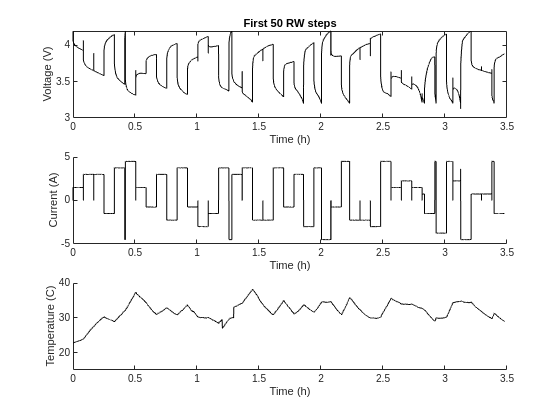

RWDis.repition{1}.indexes = 0;
counter1 = 0;
counter2 = 0;
lastStep = -1;
% find indexes of all RW steps
for i = 1:length(steps)
    if (strcmp(steps(i).comment,'discharge (random walk)')||...
            strcmp(steps(i).comment,'rest (random walk)')||...
            strcmp(steps(i).comment,'charge (random walk)'))
        % if there is a break in the step sequence then separate sequence
        % into new list
        if (i-lastStep > 1)
            counter1 = 1;
            counter2 = counter2+1;
            RWDis.repition{counter2}.indexes(counter1) = i;
        else
            counter1 = counter1+1;
            RWDis.repition{counter2}.indexes(counter1) = i;
        end
        lastStep = i;
    end
end

% identify index sequence for first 50 RW discharge cycles
inds = RWDis.repition{1}.indexes(1):RWDis.repition{1}.indexes(100);

% stich all of the indexed steps together
step = steps(inds(1));
for i = 2:length(inds)
    step.relativeTime = [step.relativeTime step.relativeTime(end)+steps(inds(i)).relativeTime];
    step.voltage = [step.voltage steps(inds(i)).voltage];
    step.current = [step.current steps(inds(i)).current];
    step.temperature = [step.temperature steps(inds(i)).temperature];
end

% plot Voltage
figure
subplot(3,1,1)
plot(step.relativeTime/3600,step.voltage,'k')
title(sprintf('First 50 RW steps',i))
xlabel('Time (h)')
ylabel('Voltage (V)')

% plot Current
subplot(3,1,2), hold on
plot(step.relativeTime/3600,step.current,'k')
xlabel('Time (h)')
ylabel('Current (A)')

% plot temperature
subplot(3,1,3), hold on
plot(step.relativeTime/3600,step.temperature,'k')
ylim([15, 40])
xlabel('Time (h)')
ylabel('Temperature (C)')

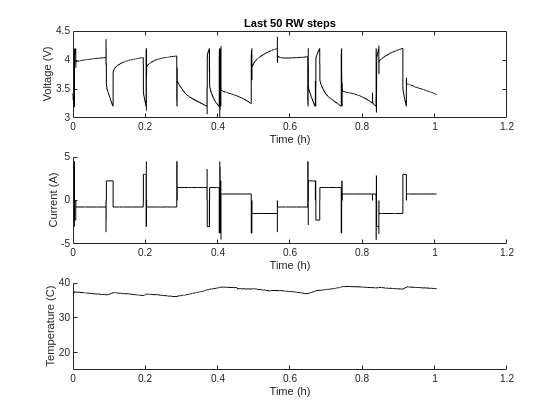


% identify index sequence for last 50 RW discharge cycles
inds = RWDis.repition{end}.indexes(end-100):RWDis.repition{end}.indexes(end);

% stich all of the indexed steps together
step = steps(inds(1));
for i = 2:length(inds)
    step.relativeTime = [step.relativeTime step.relativeTime(end)+steps(inds(i)).relativeTime];
    step.voltage = [step.voltage steps(inds(i)).voltage];
    step.current = [step.current steps(inds(i)).current];
    step.temperature = [step.temperature steps(inds(i)).temperature];
end

% plot Voltage
figure
subplot(3,1,1)
plot(step.relativeTime/3600,step.voltage,'k')
title(sprintf('Last 50 RW steps',i))
xlabel('Time (h)')
ylabel('Voltage (V)')

% plot Current
subplot(3,1,2), hold on
plot(step.relativeTime/3600,step.current,'k')
xlabel('Time (h)')
ylabel('Current (A)')

% plot temperature
subplot(3,1,3), hold on
plot(step.relativeTime/3600,step.temperature,'k')
ylim([15, 40])
xlabel('Time (h)')
ylabel('Temperature (C)')